## Example 1.1

Plot $f(x) = (x-1)^2$ over the domain $x \in [0, 2]$ 

f = @(x) x.^5 - 8*x + 2  % anonymous function

f = function_handle with value:
    @(x)x.^5-8*x+2


x = -20:0.01:20        

x =   -20.0000  -19.9900  -19.9800  -19.9700  -19.9600  -19.9500  -19.9400  -19.9300  -19.9200  -19.9100  -19.9000  -19.8900  -19.8800  -19.8700  -19.8600  -19.8500  -19.8400  -19.8300  -19.8200  -19.8100  -19.8000  -19.7900  -19.7800  -19.7700  -19.7600  -19.7500  -19.7400  -19.7300  -19.7200  -19.7100  -19.7000  -19.6900  -19.6800  -19.6700  -19.6600  -19.6500  -19.6400  -19.6300  -19.6200  -19.6100  -19.6000  -19.5900  -19.5800  -19.5700  -19.5600  -19.5500  -19.5400  -19.5300  -19.5200  -19.5100


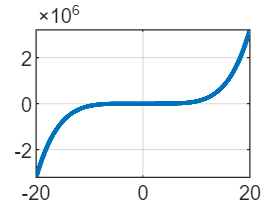


plot(x,f(x), 'linewidth', 2); grid;

## Example 1.2

Consider the ``corrugated spring'' function $f(R) = -\cos(kR) + 0.1R^2$ where $R$ is the radius $R = \sqrt{(x_1-c_1)^2 + (x_2-c_2)^2}$, $c_1 = 5$, $c_2=5$, $k=5$. Draw

- a 3D plot of this function

- a contour plot of the function in variable space or $x_1-x_2$ space

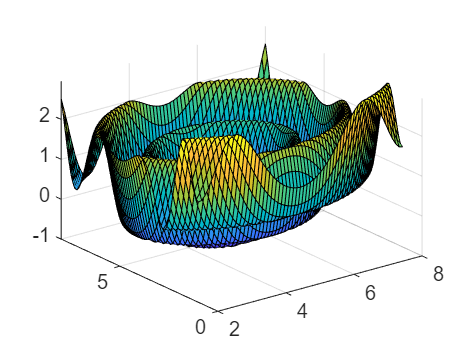

[x1, x2] = meshgrid(2:0.1:8, 1:0.1:8);
c1 = 5; c2 = 5; k = 5;
R = sqrt((x1-c1).^2 + (x2-c2).^2);
f = -cos(k*R) + 0.1*R.^2;

surf(x1, x2, f )

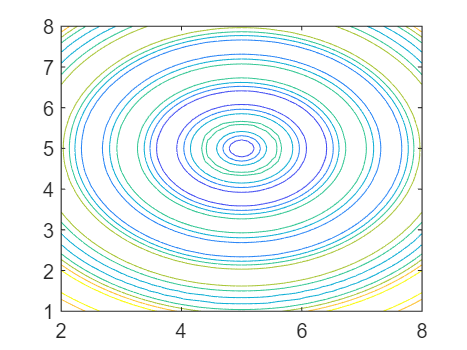

figure(2)
contour(x1, x2, f)

## Example 1.12

The plotting of feasible region $\Omega$ and objective function contours for the NLP problem


$$\begin{array}{l}
\underset{x_1 ,x_2 }{\textrm{minimize}} \;\;\;{\left(x_1 +2\right)}^2 -x_2 \\
\textrm{subject}\;\textrm{to}\;\;\;\frac{x_1^2 }{4}+x_2 -1\le 0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;2+x_{1\;} -2x_2 \le \;0
\end{array}$$


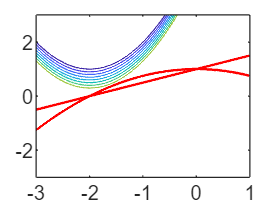

[x1, x2] = meshgrid(-3:0.01:1, -3:0.01:3);
g1 = x1.^2/4 + x2 -1;
g2 = 2 + x1 - 2*x2;
f = (x1+2).^2 -x2;

contour(x1, x2, f, -1:0.1:-0.205)
hold on

contour(x1, x2, g1, [0 0], 'LineWidth',1, 'LineColor','red') % level of g1 = 0
contour(x1, x2, g2, [0 0], 'LineWidth',1, 'LineColor','red')

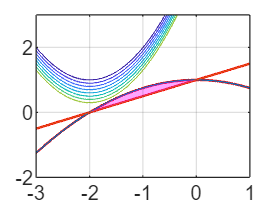

% add shading area

y1 = @(x) -x.^2/4 + 1;
y2 = @(x) 1 + x./2;
x = -3:0.1:1;

pgon1 = polyshape([ x(1) x x(end) ],[ y1(x(1)) y1(x) y1(x(end)) ], 'Simplify',false);
pgon2 = polyshape([x(1) x(1) x x(end) x(end)],[1.5 y2(x(1)) y2(x) y2(x(end)) 1.5], 'Simplify',false);

plot(x,y1(x),x,y2(x))
plot(intersect(pgon1,pgon2),'EdgeColor','none','FaceColor','m')
axis([-3 1 -2 3]); grid

hold off